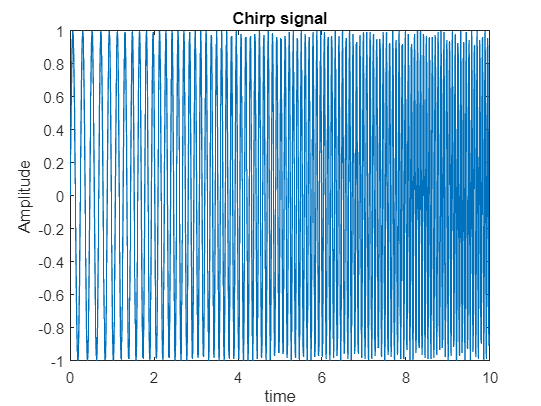

a = 1;
t = 0:(1/100):10 - (1/100);
F = (3+3*a)*(t/10)+ (2+2*a) ;
x = sin(2*pi*F.*t);
plot(t,x)
title('Chirp signal');
xlabel('time');
ylabel('Amplitude');

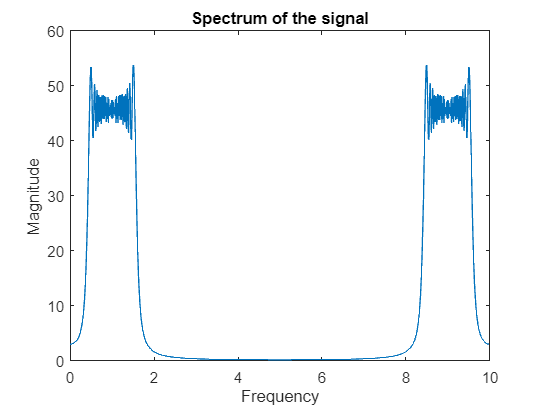

fs = 100;
y = fft(x);
p = abs(y);
plot(t,p)
title('Spectrum of the signal');
xlabel('Frequency');
ylabel('Magnitude');

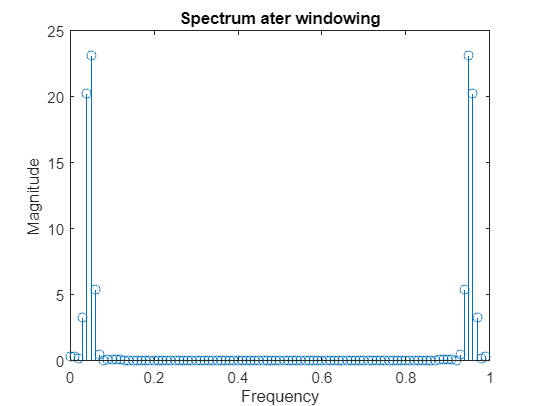

w = hamming(100);
x_1 = x(1,1:100).*transpose(w);
y_1 = fft(x_1);
p_1 = abs(y_1);
stem(t(1,1:100),p_1)
title('Spectrum ater windowing')
xlabel('Frequency');
ylabel('Magnitude');

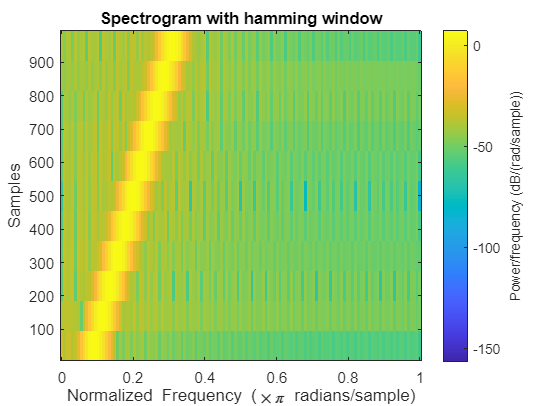

spectrogram(x,w,10);
title('Spectrogram with hamming window');

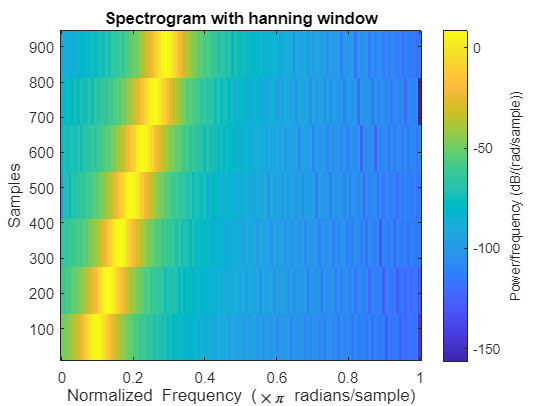

w1 = hanning(150);
spectrogram(x,w1,16);
title('Spectrogram with hanning window');

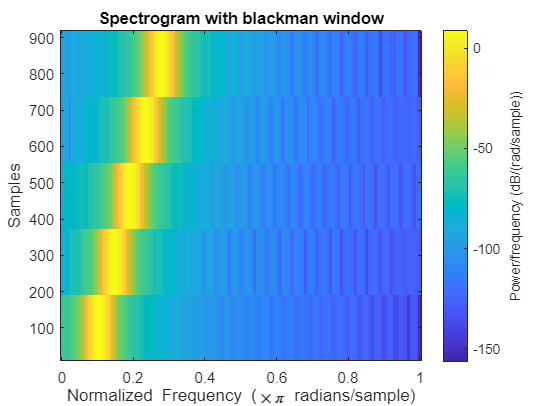

w2 = blackman(200);
spectrogram(x,w2,18);
title('Spectrogram with blackman window');